# Control and Instrumentation Lab Assignment 2

**SWARNENDU PAUL 19EE3FP18**

**Question 5.**


$$\frac{g}{l} = \frac{9.8}{2} = 4.9$$
 

As ode45 solves first order ODE only, so we have to change the given equation

$\frac{d^2\theta}{dt^2} + \frac{g}{l}sin\theta = 0$ can be written as 2 first order ODE

- 
$$\frac{d\theta'(t)}{dt}= -4.9sin\theta(t)$$


- 
$$\frac{d\theta(t)}{dt}=\theta'(t)$$


This function is described in pen1.m script.

Now we use ode45 as well as functions we have generated(euler_sol,RK4_sol) to calculate $\theta(t)$in the interval [0,20s].

using ode45:

t1=0:0.1:20;
t2=0:0.01:20;
[t1,x1]=ode45(@pen1,t1,[2 0]);
[t2,x2]=ode45(@pen1,t2,[2 0]);

using euler sol:

[t3,x3]=euler_sol(@pen1,0,20,[2 0],0.1);
[t4,x4]=euler_sol(@pen1,0,20,[2 0],0.01);

using RK4_sol

[t5,x5]=RK4_sol(@pen1,0,20,[2 0],0.1);
[t6,x6]=RK4_sol(@pen1,0,20,[2 0],0.01);

Now, these results are plotted using subplot command.

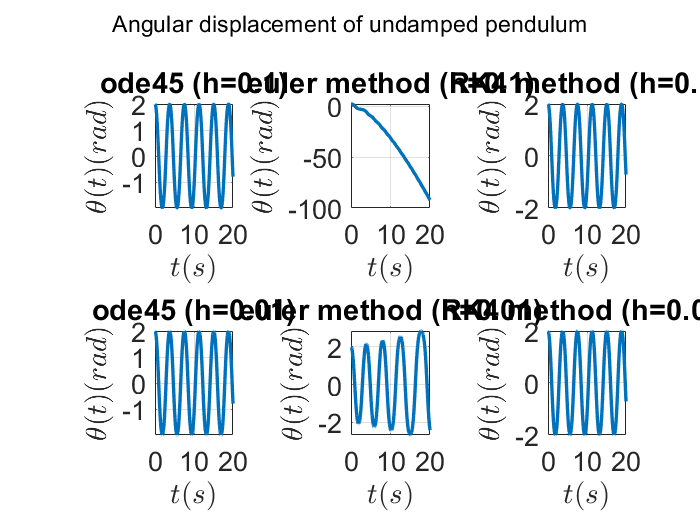

figure
subplot(2,3,1)
plot(t1,x1(:,1),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("ode45 (h=0.1)");
subplot(2,3,2)
plot(t3,x3(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("euler method (h=0.1)");
subplot(2,3,3)
plot(t5,x5(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("RK4 method (h=0.1)");
subplot(2,3,4)
plot(t2,x2(:,1),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("ode45 (h=0.01)");
subplot(2,3,5)
plot(t4,x4(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("euler method (h=0.01)");
subplot(2,3,6)
plot(t6,x6(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("RK4 method (h=0.01)");
sgtitle("Angular displacement of undamped pendulum");

The RK4_sol function as well as ode45, which is built using the RK4 method, gives almost equal and perfect data for the angular displacement of simple undamped pendulum. While the euler formula is not useful at all for larger values of h.

Now, we move towards damped pendulum.

We know, for a damped pendulum, equation of motion is,


$$\frac{d^2\theta}{dt^2} + \frac{b}{m}\frac{d\theta}{dt} + \frac{mg}{L(m-2b)} sin\theta =0$$
 

given values, 

$g=9.8 m/s^2$ , $L=2 m$ , $m=1kg$, $b=0.3$

so $\frac{b}{m} = 0.3$  and $\frac{mg}{L(m-2b)} = 12.25$ 

Again we can write it as 2 first order ODE

- 
$$\frac{d\theta'(t)}{dt} = -0.3\theta'(t) - 12.25sin\theta(t)$$


- 
$$\frac{d\theta(t)}{dt} = \theta'(t)$$


This function is described in pen2.m script.

Now we use ode45 as well as functions we have generated(euler_sol,RK4_sol) to calculate $\theta(t)$in the interval [0,20s].

using ode45:

[t1,y1]=ode45(@pen2,t1,[2 0]);
[t2,y2]=ode45(@pen2,t2,[2 0]);

using euler sol:

[t3,y3]=euler_sol(@pen2,0,20,[2 0],0.1);
[t4,y4]=euler_sol(@pen2,0,20,[2 0],0.01);

using RK4_sol

[t5,y5]=RK4_sol(@pen2,0,20,[2 0],0.1);
[t6,y6]=RK4_sol(@pen2,0,20,[2 0],0.01);

Now, these results are plotted using subplot command.

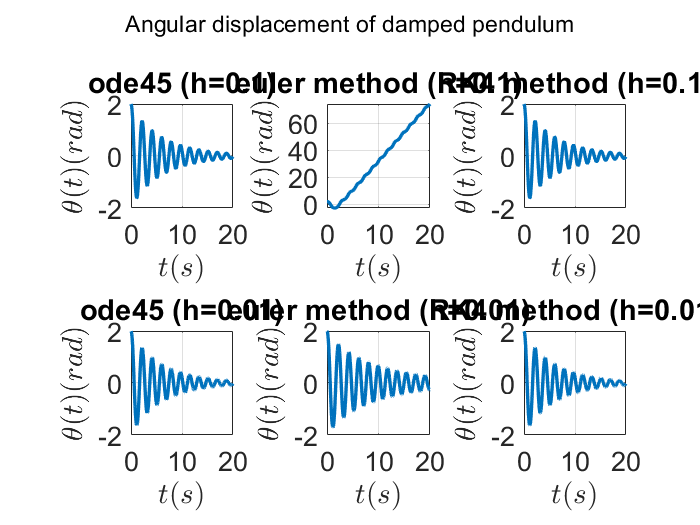

figure
subplot(2,3,1)
plot(t1,y1(:,1),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("ode45 (h=0.1)");
subplot(2,3,2)
plot(t3,y3(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16);
title("euler method (h=0.1)");
subplot(2,3,3);
plot(t5,y5(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16)
title("RK4 method (h=0.1)");
subplot(2,3,4);
plot(t2,y2(:,1),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16)
title("ode45 (h=0.01)");
subplot(2,3,5);
plot(t4,y4(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16)
title("euler method (h=0.01)");
subplot(2,3,6)
plot(t6,y6(1,:),'LineWidth',2);
xlabel("$t(s)$","Interpreter","latex");
ylabel("$\theta(t) (rad)$","Interpreter","latex");
grid on
set(gca,'Fontsize',16)
title("RK4 method (h=0.01)");
sgtitle("Angular displacement of damped pendulum");